clc
%addpath('C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab')
%savepath
%dr = loadvec('Basler_acA2040-90uc__21599070__20240408_111238612_0001_diff.dat')
dr = loadvec('C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Input\20240408\Results\Basler_acA2040-90uc__21599070__20240408_111238612_0002_diff_new.dat');
%A = importdata('vp__avg_piv.dat')
%A.data


% TO EMPTY CELLS CORRESPONDING WITH BLACK PARTS OF MASK
% Load the image
image = imread('C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Input\20240408\20240408mask.tif');

% Convert to binary mask
binary_mask = imbinarize(im2gray(image)); % Convert to grayscale and threshold

% Assuming your table is stored in a variable named 'your_table'

% Identify the indices of black parts in the mask
[row, col] = find(binary_mask == 0)

row =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


col =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


size(row)

ans =      1420250           1


size(col)

ans =      1420250           1


numel(row)

ans = 1420250

max(row(i))

ans = 255


size(dr.vx)

ans =    254   254


% Adjust coordinates to match the table size
row = ceil(row / 8);
col = ceil(col / 8);

% Now, empty the corresponding cells in your table
for i = 1:numel(row)
    dr.vx(row(i), col(i)); % = []; % Empty the cell
end

Index in position 1 exceeds array bounds. Index must not exceed 254.

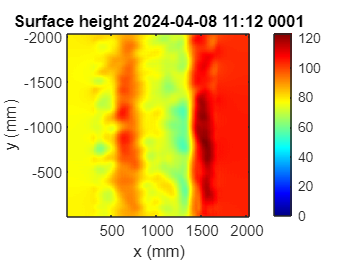

h_0 = 13/0.15; % 1 pixel is 0.15 mm % 11 mm % surface-pattern distance in mm
h = surfheight(dr,h_0);
showf(h)
title('Surface height 2024-04-08 11:12 0001')
colorbar;

%caxis([60, 85]);
%w=h.w
%save('20240408_1112_surface_0001.mat','h')

%dr.vy(dr.vy==0)=NaN;
%dr.vy
%dr.vx